# Practice 6

Name: Zhu Chenhao

HDU ID: 22320630

## 1. Calculation

        System 1:


$$\begin{array}{l}
{\dot{x} }_1 =-x_1 +x_2 \\
{\dot{x} }_2 =2{x_1 }^3 x_2 +x_1 -u
\end{array}$$


        linearize the system:


$$\begin{array}{l}
u=2{x_1 }^3 x_2 +2x_1 -x_2 +v\\
{\dot{z} }_1 =z_2 \\
{\dot{z} }_2 =v\\
v=-k_1 z_1 -k_2 z_2 
\end{array}$$


        System 2:


$$\begin{array}{l}
{\dot{x} }_1 =-x_1 +x_2 -x_3 \\
{\dot{x} }_2 =-x_1 x_3 -x_2 +u\\
{\dot{x} }_3 =-x_1 +u
\end{array}$$


        linearize the system:


$$\begin{array}{l}
u=-\frac{-v-3x_1 +4x_2 -2x_3 +3x_1 x_3 -x_2 x_3 +x_3^2 +x_1^2 }{1+x_1 }\\
z=T(x):=\left\lbrack \begin{array}{cccccccccccccccccccc}
x_1 \\
-x_1 +x_2 -x_3 \\
2x_1 -2x_2 +x_3 -x_1 x_3 
\end{array}\right\rbrack \\
{\dot{z} }_1 =z_2 \\
{\dot{z} }_2 =z_3 \\
{\dot{z} }_3 =v\\
v=-k_1 z_1 -k_2 z_2 -k_3 z_3 
\end{array}$$


## 2. Simulation

## System 1: 

### k1 = k2 = 2 

### initial condition:(1, -1)

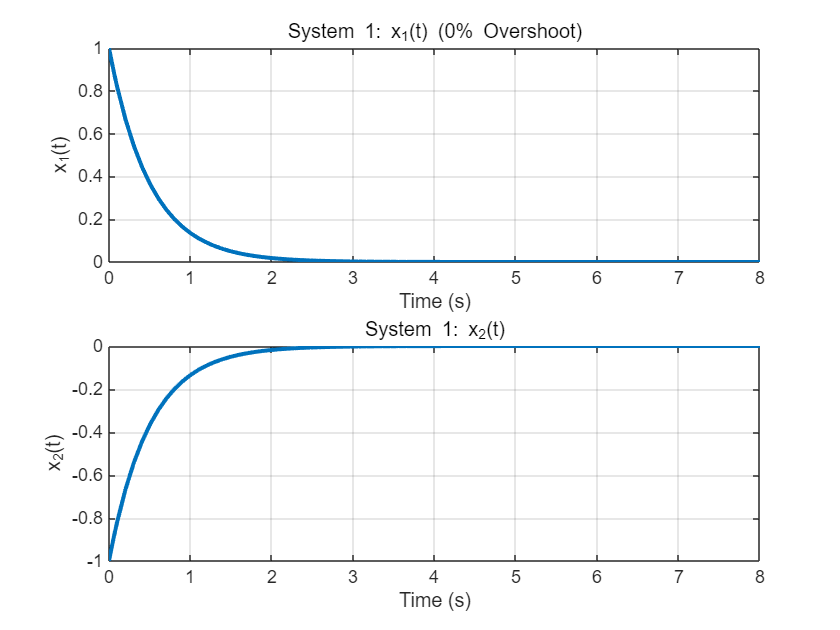

clc; clear; close all;
% Initial conditions
x0 = [1; -1];
tspan = [0 8];
a = 2;
k1 = a^2;
k2 = 2*a;

odefun = @(t, x) [
    -x(1) + x(2);
    2*x(1)^3 * x(2) + x(1) - (2*x(1) + 2*x(1)^3*x(2) - x(2) - (-k1*x(1) - k2*(-x(1) + x(2)))) % dx2/dt (with control u)
];

[t, x] = ode45(odefun, tspan, x0);

figure;
subplot(2,1,1);
plot(t, x(:,1), 'LineWidth', 2);
title('System 1: x_1(t) (0% Overshoot)');
xlabel('Time (s)'); ylabel('x_1(t)'); grid on;

subplot(2,1,2);
plot(t, x(:,2), 'LineWidth', 2);
title('System 1: x_2(t)');
xlabel('Time (s)'); ylabel('x_2(t)'); grid on;

## System 2

### k1 = 6; k2 = 11; k3 = 6

### initial condition:(1, 0.5, 0)

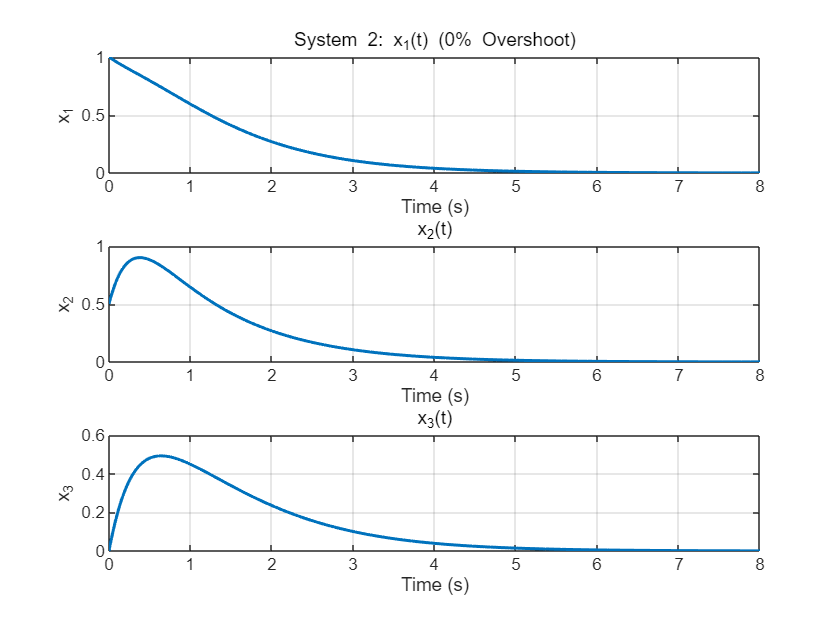


clear; clc;

poles = [-1, -2, -3];
k1 = abs(poles(1)*poles(2)*poles(3)); % 6
k2 = abs(poles(1)*poles(2) + poles(2)*poles(3) + poles(1)*poles(3)); % 11
k3 = abs(sum(poles)); % 6

tspan = [0 8];

x0 = [1; 0.5; 0];

v = @(x) -k1*x(1) - k2*(-x(1) + x(2) - x(3)) - k3*(2*x(1) - 2*x(2) + x(3) - x(1)*x(3));
u = @(x) (-v(x) - 3*x(1) + 4*x(2) - 2*x(3) + 3*x(1)*x(3) - x(2)*x(3) + x(3)^2 + x(1)^2) / max(1e-3, 1 + x(1));

odefun = @(t, x) [
    -x(1) + x(2) - x(3);
    -x(1)*x(3) - x(2) + u(x);
    -x(1) + u(x)
];

options = odeset('RelTol', 1e-6);
[t, x] = ode45(odefun, tspan, x0, options);

figure;
subplot(3,1,1);
plot(t, x(:,1), 'LineWidth', 1.5);
title('System 2: x_1(t) (0% Overshoot)');
xlabel('Time (s)'); ylabel('x_1');
grid on;

subplot(3,1,2);
plot(t, x(:,2), 'LineWidth', 1.5);
title('x_2(t)');
xlabel('Time (s)'); ylabel('x_2');
grid on;

subplot(3,1,3);
plot(t, x(:,3), 'LineWidth', 1.5);
title('x_3(t)');
xlabel('Time (s)'); ylabel('x_3');
grid on;

## Conclusion

Both ��feedback linearization�� and ��linearization at a point (Jacobian linearization)�� are techniques used to control nonlinear systems, but they differ significantly in their approaches, advantages, and limitations.��

Feedback Linearization���� **Advantages**:��

Exact Linearization��:

Transforms the ��entire nonlinear system�� into a linear one through exact state transformations and feedback, rather than approximation.

Works globally (across the entire state space) if the system is feedback-linearizable.

��Preserves Nonlinearity��:

Unlike Jacobian linearization, it does not discard nonlinear terms—instead, it cancels them out via control.

Useful for systems with ��strong nonlinearities�� that cannot be ignored.

��Better Performance��:

Can achieve ��precise tracking and stabilization�� since the linearization is exact.

Allows for ��pole placement�� in the transformed coordinates.

�**�Disadvantages:**��

Requires Precise Model Knowledge��:

The exact cancellation of nonlinearities depends on ��perfect knowledge�� of system dynamics.

Model uncertainties�� or disturbances can degrade performance.

Complexity��:

Requires ��coordinate transformations�� and may involve solving partial differential equations (PDEs) to find the right transformation.

Not all systems are feedback-linearizable (must satisfy ��involutivity conditions��).